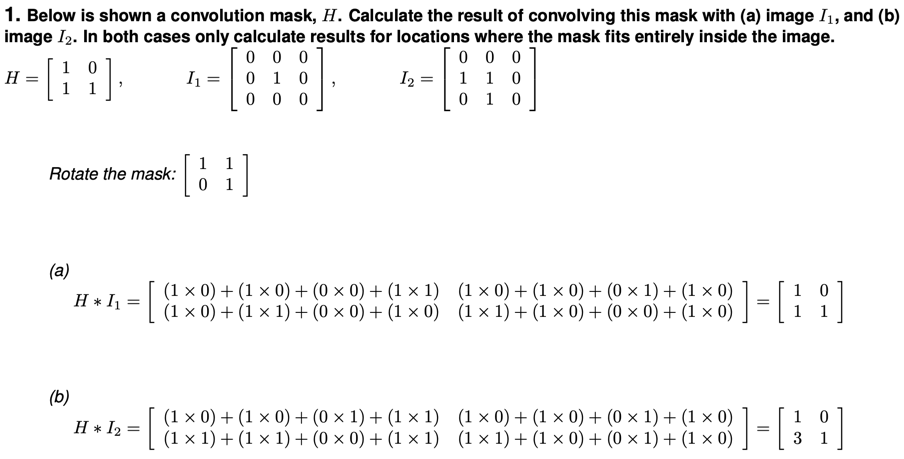

H = [1 0
     1 1];
I1 = [0 0 0
      0 1 0
      0 0 0];
I2 = [0 0 0
      1 1 0
      0 1 0];

a = conv2(I1, H, "valid")

a =      1     0
     1     1


b = conv2(I2, H, "valid")

b =      1     0
     3     1


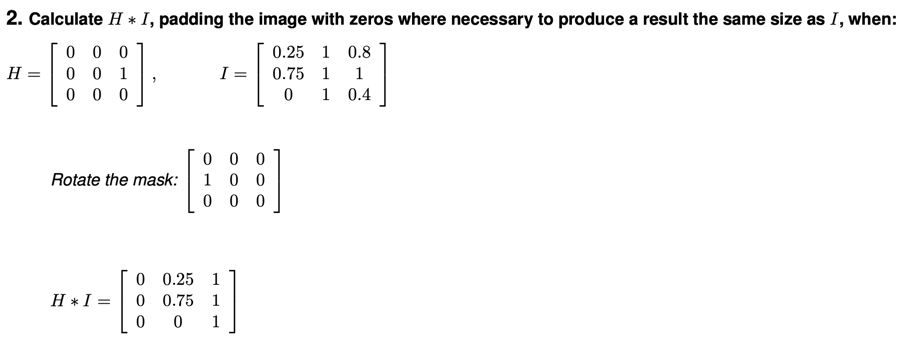

H = [0 0 0
     0 0 1
     0 0 0];
I = [0.25 1 0.8
     0.75 1 1
     0 1 0.4];

conv2(I, H, "same")

ans =          0    0.2500    1.0000
         0    0.7500    1.0000
         0         0    1.0000


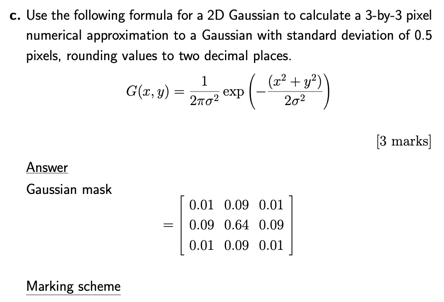

% 2016-2017, p11
std = 0.50;
mask = zeros(3);
for y = -1:1
    for x = -1:1
        mask(y+2, x+2) = g(x,y,std);
    end
end
mask = round(mask, 2)

mask =     0.0100    0.0900    0.0100
    0.0900    0.6400    0.0900
    0.0100    0.0900    0.0100


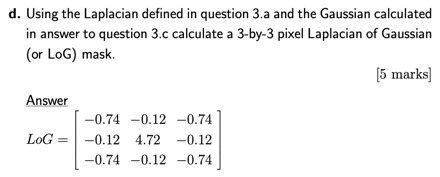

% 2016-2017, p11
L = [-1 -1 -1
     -1 8 -1
     -1 -1 -1];

conv2(L, mask, "same")

ans =    -0.7400   -0.1200   -0.7400
   -0.1200    4.7200   -0.1200
   -0.7400   -0.1200   -0.7400


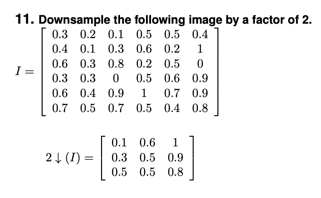

I = [0.3 0.2 0.1 0.5 0.5 0.4
     0.4 0.1 0.3 0.6 0.2 1
     0.6 0.3 0.8 0.2 0.5 0
     0.3 0.3 0 0.5 0.6 0.9
     0.6 0.4 0.9 1 0.7 0.9
     0.7 0.5 0.7 0.5 0.4 0.8];

factor = 2;

I(factor:factor:end, factor:factor:end)

ans =     0.1000    0.6000    1.0000
    0.3000    0.5000    0.9000
    0.5000    0.5000    0.8000


function out = g(x, y, std)
    out = (1 / (2 * pi * std^2)) * exp(- (x^2 + y^2) / (2 * std^2));
end